# Actividad 2.2 (Parametrización de trayectorias)

**Bruno Manuel Zamora Garcia A01798275**

Para convertir la figura de una estrella a un rombo, cambié el rango del vector `tiempo` de `[1:1:6]` a `[1:1:5]` porque el rombo solo necesita 4 vértices más uno para cerrar la figura. También ajusté la normalización del ángulo de `[pi, 5*pi]` a `[pi, 11*pi]` para que los puntos se distribuyan formando un rombo en lugar de una estrella. Además, modifiqué los vectores `x3` e `y3` para que tengan 5 elementos en lugar de 6.

**Rombo**

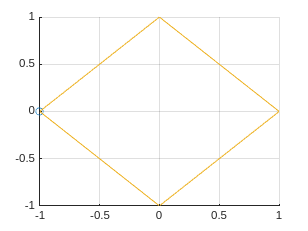

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
tiempo=[1:1:5];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
%theta
t2= normalize(tiempo,"range",[pi,11*pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x3= ones(1,5).*cos(t2);
y3=ones(1,5).*sin(t2);

%graficamos la trayectoria
figure(6)
comet(x3, y3)
grid("on")

Para modificar el código de la estrella y generar un hexágono, aumenté el número de puntos en el vector `tiempo`, cambiándolo de `[1:1:6]` a `[1:1:7]`, ya que el hexágono necesita 6 vértices y uno adicional para cerrar la figura. También mantuve el rango de normalización de `[pi, 11*pi]`, que permite distribuir los puntos uniformemente en el círculo para formar un polígono regular. Finalmente, ajusté los vectores `x3` e `y3` a tamaño 7 para que coincidan con la cantidad de puntos y así se trace correctamente la figura.

**Hexagono**

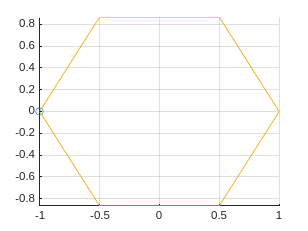

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
tiempo=[1:1:7];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
%theta
t2= normalize(tiempo,"range",[pi,11*pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x3= ones(1,7).*cos(t2);
y3=ones(1,7).*sin(t2);

%graficamos la trayectoria
figure(6)
comet(x3, y3)
grid("on")

Para generar un dodecágono a partir del código de la estrella, cambié el vector `tiempo` de `[1:1:6]` a `[1:1:13]`, ya que el dodecágono tiene 12 vértices y uno adicional para cerrar la figura. También modifiqué el rango de normalización del ángulo a `[pi, 23*pi]` para distribuir los 13 puntos de forma simétrica alrededor del círculo. Además, ajusté los vectores `x3` e `y3` para que tengan 13 elementos y así se trace correctamente la figura completa.

**Dodecagono**

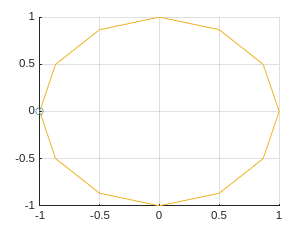


%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
tiempo=[1:1:13];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
%theta
t2= normalize(tiempo,"range",[pi,23*pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x3= ones(1,13).*cos(t2);
y3=ones(1,13).*sin(t2);

%graficamos la trayectoria
figure(6)
comet(x3, y3)
grid("on")

**Flor 10 petalos**

Solo se cambia el numero por el que multiplica a 't' dentro del cos de x y y por el numero de petalos que queremos. Ejemplo: 

x = 50*cos(10*t) .* cos(t)

y = 50*cos(10*t) .* sin(t)

En este codigo esta un 10 por lo que habra 10 petalos, si queremos 15 tendra que ser un 15.

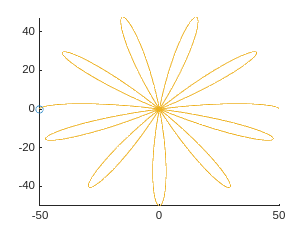

tiempo=[0:0.01:10];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
%theta
t= normalize(tiempo,"range",[0,pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x= 50*cos(10*t).*cos(t);
y=50*cos(10*t).*sin(t);
%graficamos la trayectoria
figure(3)
comet(x,y)

**Flor 15 petalos**

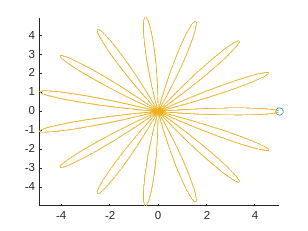

tiempo=[0:0.01:10];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
%theta
t= normalize(tiempo,"range",[0,pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x= 5*cos(15*t).*cos(t);
y=5*cos(15*t).*sin(t);
%graficamos la trayectoria
figure(3)
comet(x,y)

**Flor 100 petalos**

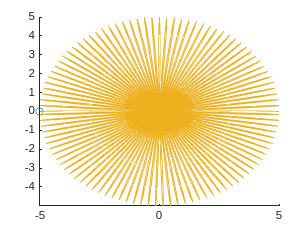

tiempo=[0:0.01:10];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
%theta
t= normalize(tiempo,"range",[0,pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x= 5*cos(100*t).*cos(t);
y=5*cos(100*t).*sin(t);
%graficamos la trayectoria
figure(3)
comet(x,y)